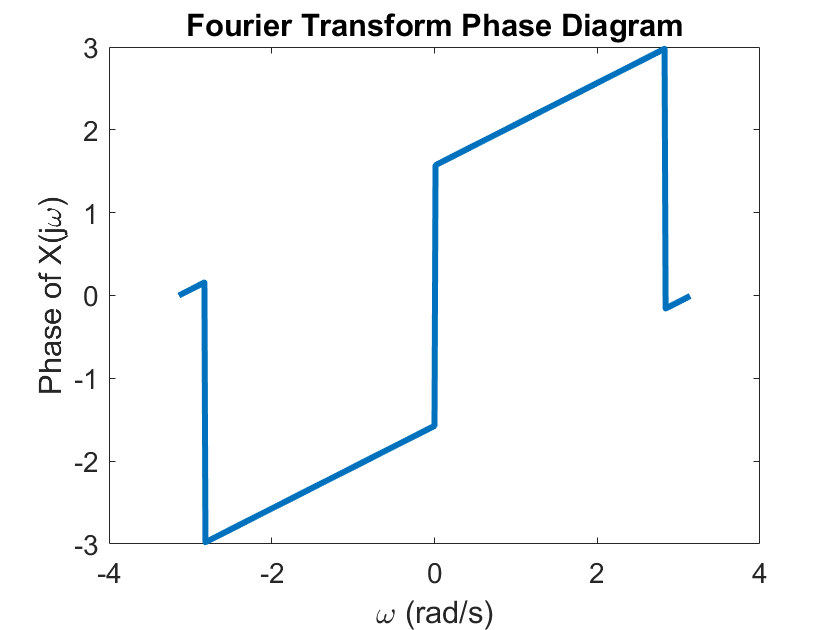

t = 0:0.01:5;
f0 = 5;
x = cos(2*pi*f0*t);
N = length(x);
w = linspace(-pi, pi, N);  % Creating the frequency axis based on FFT output
X = fft(x);

% Plot the phase diagram
figure;
plot(w, angle(X), 'linewidth', 3);
set(gca, 'fontsize', 14);
xlabel('\omega (rad/s)');
ylabel('Phase of X(j\omega)');
title('Fourier Transform Phase Diagram');